load("pc_fmu2_10s.mat");


file_transient_10s = "transient_output_10s.xlsx";
writematrix(pc_fmu2_10s, file_transient_10s);

t10 = pc_fmu2_10s(1,:);

voltages_10s = pc_fmu2_10s(21:24,:);
mf_anode_10s = pc_fmu2_10s(4:7,:);
anode_st = pc_fmu2_10s(9,:);

voltages_steady = zeros(4,101);
mf_steady = zeros(4,101);

for j=1:101
    if j<=51
        voltages_steady(:,j) = voltages(:,j);
        mf_steady(:,j) = anode_out_mf(:,j);
    else
        voltages_steady(:,j) = voltages(:,51);
        mf_steady(:,j) = anode_out_mf(:,51);
    end
end

voltages_steady

voltages_steady =          0  298.4228  302.1685  301.9866  301.2306  300.5159  300.0121  299.6835  299.4413  299.2931  299.2128  299.1720  299.1549  299.1514  299.1553  299.1624  299.1706  299.1786  299.1857  299.1916  299.1966  299.2005  299.2036  299.2060  299.2078  299.2092  299.2102  299.2110  299.2115  299.2119  299.2122  299.2125  299.2126  299.2127  299.2128  299.2129  299.2129  299.2129  299.2130  299.2130  299.2130  299.2130  299.2130  299.2130  299.2130  299.2130  299.2130  299.2130  299.2130  299.2130
         0   62.3114   59.6179   58.5566   57.8065   57.3118   56.9828   56.7728   56.6498   56.5793   56.5399   56.5197   56.5113   56.5095   56.5114   56.5150   56.5191   56.5232   56.5267   56.5299   56.5325   56.5345   56.5362   56.5375   56.5385   56.5392   56.5398   56.5402   56.5406   56.5408   56.5410   56.5411   56.5412   56.5413   56.5414   56.5414   56.5414   56.5415   56.5415   56.5415   56.5415   56.5415   56.5415   56.5415   56.5415   56.5415   56.5415   56.5415 

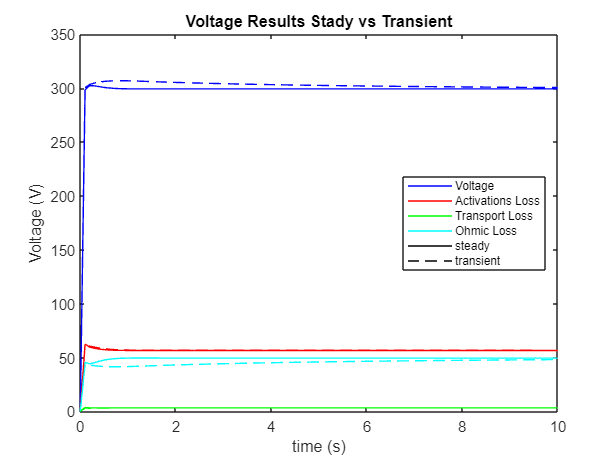


plot(t10,voltages_steady(1,:),"b", t10, voltages_steady(2,:),"r" , t10, voltages_steady(3,:),"g", t10, voltages_steady(4,:),"c")
hold on
plot(t10, t10+350, "k")
plot(t10, t10+400, "k--")
plot(t10,voltages_10s(1,:),"b--", t10, voltages_10s(2,:),"r--" , t10, voltages_10s(3,:),"g--", t10, voltages_10s(4,:),"c--")
ylim([0,350])
legend("Voltage" , "Activations Loss" , "Transport Loss" , "Ohmic Loss", "steady" , "transient","Location" , "east",'Fontsize', 8)
xlabel("time (s)")
ylabel("Voltage (V)")
title("Voltage Results Stady vs Transient")
hold off

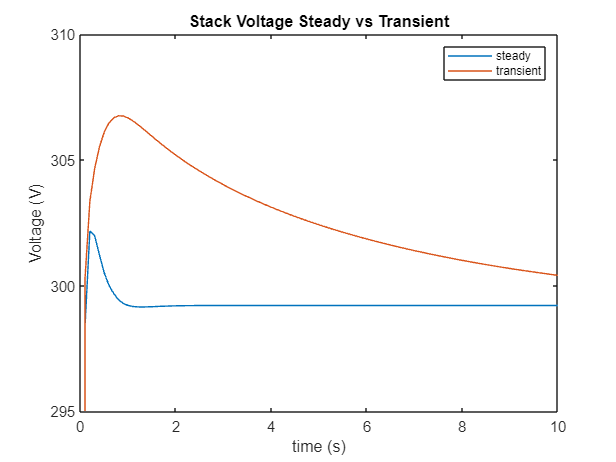


plot(t10, voltages_steady(1,:), t10, voltages_10s(1,:))
hold on
ylim([295,310])
legend("steady" , "transient","Location" , "northeast",'Fontsize', 8)
xlabel("time (s)")
ylabel("Voltage (V)")
title("Stack Voltage Steady vs Transient")
hold off

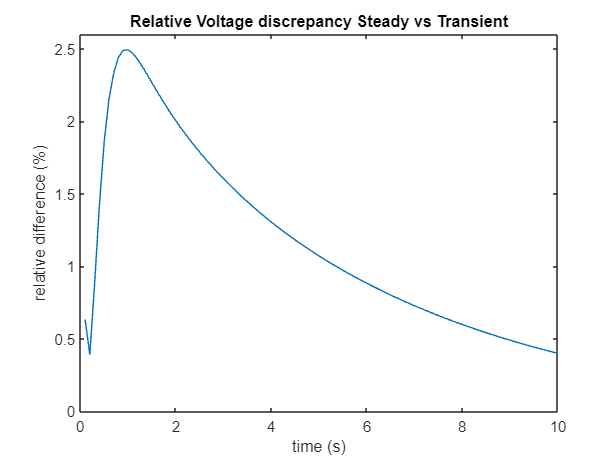



voltage_diff_10s = (abs(voltages_steady-voltages_10s)./voltages_steady)*100;

plot(t10, voltage_diff_10s(1,:))
hold on
ylim([0,2.6])
xlabel("time (s)")
ylabel("relative difference (%)")
title("Relative Voltage discrepancy Steady vs Transient")
hold off

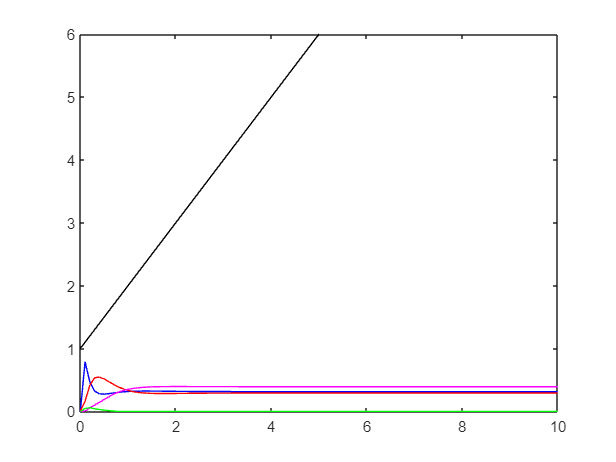




plot(t10, mf_steady(1,:), "b" , t10 , mf_steady(2,:), "r" , t10 , mf_steady(3,:), "m" ,t10,mf_steady(4,:), "g")
hold on
plot(t, (t+1), "k")

plot(t2, (t2+1), "k--")

Unrecognized function or variable 't2'.

plot(t10, mf_anode_10s(1,:), "b--" , t10 , mf_anode_10s(2,:), "r--" , t10 , mf_anode_10s(3,:), "m--" ,t10,mf_anode_10s(4,:), "g--")
xlim([0, 10])
ylim([0, 0.6])
legend("H2" , "N2" , "H2O_vap" , "H2O_liq", "steady" , "transient" , "Location" , "southeast" ,'Fontsize', 8)
xlabel("time (s)")
ylabel("mass fractions (-)")
title("Anode outlet mass fractions Steady vs Transient")
hold off

mf_diff_10s = (abs(mf_anode_10s - mf_steady)./mf_end_pc)*100;

plot(t10 , mf_diff_10s(1,:), "b", t10 , mf_diff_10s(2,:), "r", t10 , mf_diff_10s(3,:), "m", t10 , mf_diff_10s(4,:), "g")
hold on
xlim([0, 10])
ylim([0, 25])
legend("H2" , "N2" , "H2O_vap" , "H2O_liq", "Location" , "northeast" ,'Fontsize', 8)
xlabel("time (s)")
ylabel("relative difference (%)")
title("Realative Difference of species mass fractions")
hold off

plot(t10 , mf_diff_10s(1,:), "b", t10 , mf_diff_10s(2,:), "r", t10 , mf_diff_10s(3,:), "m", t10 , mf_diff_10s(4,:), "g")
hold on
xlim([7, 10])
ylim([0, 0.7])
legend("H2" , "N2" , "H2O_vap" , "H2O_liq", "Location" , "northeast" ,'Fontsize', 8)
xlabel("time (s)")
ylabel("relative difference (%)")
title("Realative Difference of species mass fractions - close up")
hold off